# Estimación de parámetros utilizando mamática simbólica

## Preparación previa a la estimación de parámetros

**1.** Definir los estados y los parámetros del modelo 

syms P(t) D(t)
syms alpha beta delta gamma

**2. **Se definen las ecuaciones 

ode1 = diff(P) == alpha*P - beta*P*D;
ode2 = diff(D) == delta*D*P - gamma*D;

odes = [ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}P\left(t\right)=\alpha \,P\left(t\right)-\beta \,\text{D}\left(t\right)\,P\left(t\right)\\ \frac{\partial }{\partial t}\text{D}\left(t\right)=\delta \,\text{D}\left(t\right)\,P\left(t\right)-\gamma \,\text{D}\left(t\right) \end{array}\right)$$

vars = [P D];

**3. **Definir el tiempo de simulación

domain = [0 20];

**4**. Utilizar la función gsua_dataprep para determinar orden de ingreso de los intervalos de los factores (parámetros y condiciones iniciales).

modelName = 'Lotka-Volterra';
gsua_dataprep(odes, vars, domain, modelName);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccc} P\left(t\right) & \text{D}\left(t\right) & \alpha & \beta & \delta & \gamma \end{array}\right)$$

**5.** Ingresar los intervalos de los factores de acuerdo al orden anteriormente mencionado

Ranges = [2 5;       %P(0)
          2 5;       %D(0)
          0 1;       %alpha
          0 1;       %beta
          0 1;       %delta 
          0 1        %gamma
          ];

**6. **Creación del objeto tipo tabla que se utilizará para hacer la estimación de parámetros 

[T, ~] = gsua_dataprep(odes, vars, domain, modelName, 'Range', Ranges)

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccc} P\left(t\right) & \text{D}\left(t\right) & \alpha & \beta & \delta & \gamma \end{array}\right)$$

T = 6×2 table
             Range     Nominal
             ______    _______

    P0       2    5      3.5  
    D0       2    5      3.5  
    alpha    0    1      0.5  
    beta     0    1      0.5  
    delta    0    1      0.5  
    gamma    0    1      0.5  


**7. **Simulación de los valores nominales de la tabla para "crear datos reales"

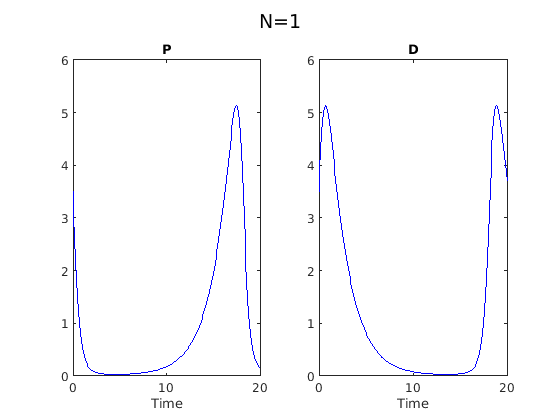

xdata = 0 : 0.1 : 20;
y = gsua_eval(T.Nominal, T, xdata);

**8. **Creación de los datos reales y su graficación

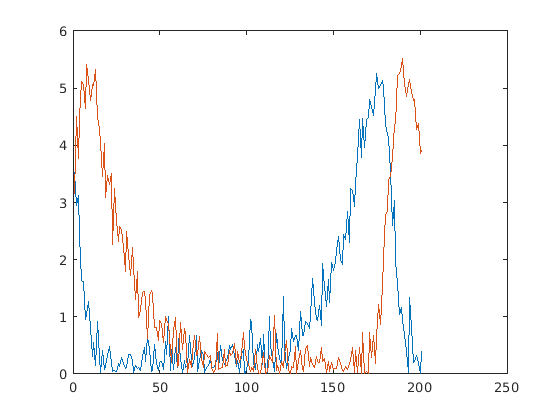

figure
noise = normrnd(0, 0.3, [size(xdata), 2]);
ydata = abs(y + squeeze(noise)');
plot(ydata')

## Estimación de parámetros

**1.** Definir que salida del modelo se utilizará para hacer la estimación de parámetros

T.Properties.CustomProperties.output = 1;

**2. **Definir el número de estimaciones 

N = 10;

**3.** Definir las opciones de estimación (algoritmo de optimización, usar paralelo...)

opt = optimoptions('lsqcurvefit', 'UseParallel',false,'Display','off');
solver = 'lsqc';

**4.** Usar la función de estimación de parámetros guardando los parámetros estimado en una tabla *T_est* 

[T_est, ~] = gsua_pe(T, xdata, ydata(1, :), 'solver', solver, 'N', N, 'opt', opt); 

Generating a valid matrix for estimations


Estimation 1


Estimation 2


Estimation 3


Estimation 4


Estimation 5


Estimation 6


Estimation 7


Estimation 8


Estimation 9


Estimation 10


**5. **Comparar las estimaciones realizadas con los datos reales (usando la salida estimada)

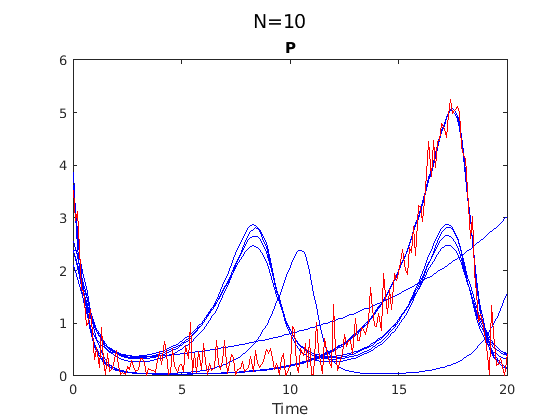

figure
gsua_eval(T_est.Estlsqc, T_est, xdata, ydata);

**6. **Comparar las estiamciones realizadas con los datos reales (usando ambos estados del modelo)

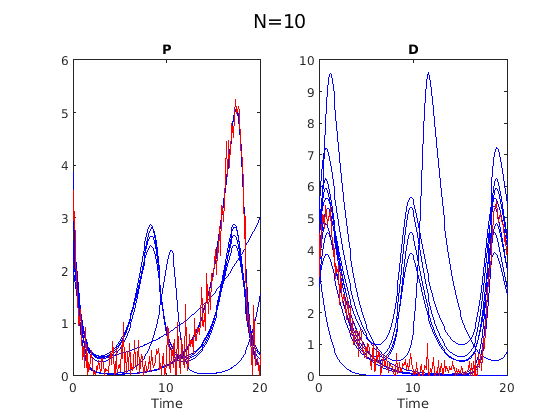

figure
T_est.Properties.CustomProperties.output = [1, 2];
gsua_eval(T_est.Estlsqc, T_est, xdata, ydata);

##  Análisis de identificabilidad para las estimaciones de parámetros

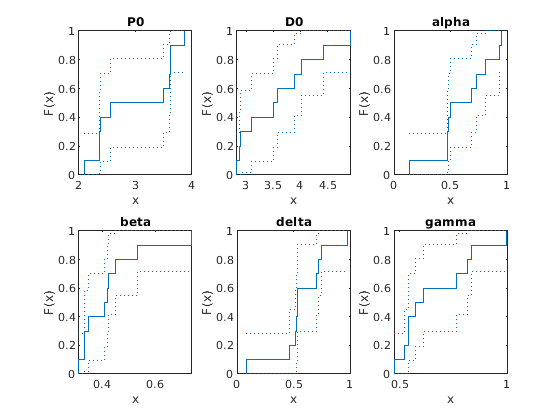

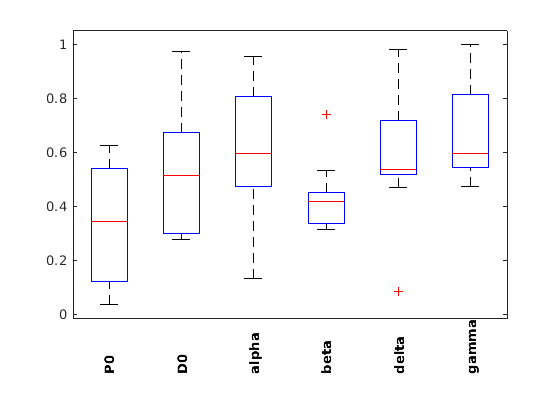

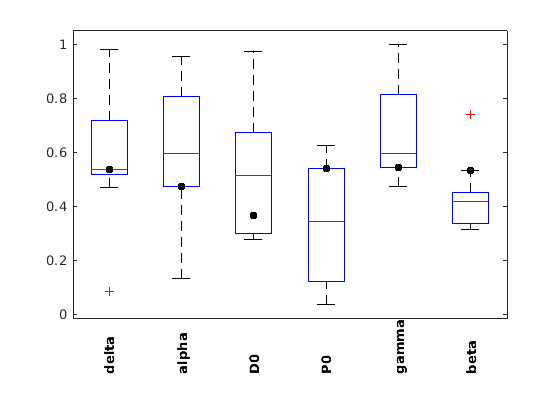

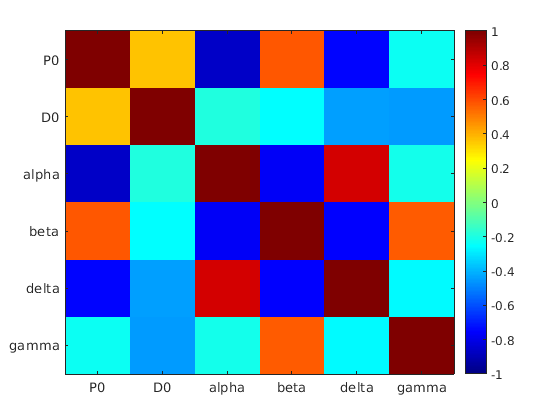

T = 6×5 table
                   Range           Nominal       Estlsqc            Est          index 
             __________________    _______    _____________    _____________    _______

    P0        2.4916     3.5663      3.029    [1×10 double]    [1×10 double]    0.50288
    D0        2.9894     4.0899     3.5396    [1×10 double]    [1×10 double]     0.3372
    alpha    0.39767    0.79115    0.59441    [1×10 double]    [1×10 double]    0.52462
    beta     0.31747    0.51486    0.41617    [1×10 double]    [1×10 double]    0.47014
    delta    0.35318    0.71671    0.53494    [1×10 double]    [1×10 double]     0.5164
    gamma    0.45902    0.72892    0.59397    [1×10 double]    [1×10 double]    0.33156


T_est.Properties.CustomProperties.output=1;
T_ia = gsua_ia(T_est, T_est.Estlsqc,false,false);

## **Análisis de incertidumbre para los parámetros de la mediana (obtenidos a partir de la estimación de parámetros)**

**1. **Definición de los conjuntos de parámetros a revisar (matriz M)

N = 100; %número de simulaciones
M = gsua_dmatrix(T_ia,N,'Method','Sobol');

**2. **Correr el análisis de incertidumbre

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 16:32:22
Number of simulations: 100


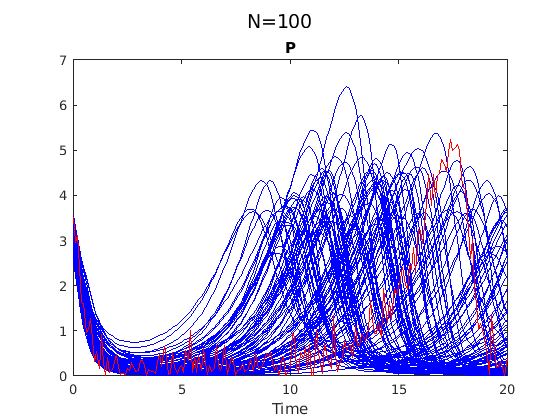

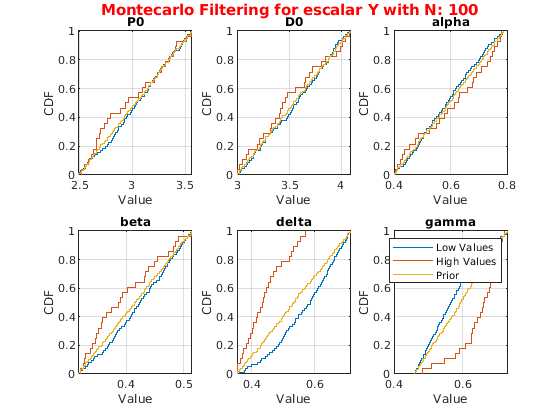

gsua_ua(M,T_ia,'xdata',xdata,'ynom',ydata(1,:),'parallel',false);

## **OPCIONAL:** Estimación de parámetros con multiples curvas

**1. **Definición de las múltiples salidas del modelo que se ajustarán

T.Properties.CustomProperties.output = [1,2];

**2. **Número de estimaciones

N = 10;

**3. **Configuración del algoritmo de estimación

opt = optimoptions('lsqcurvefit','UseParallel',false,'Display','off');
solver = 'lsqc';

**4.** Usar la función de estimación de parámetros guardando los parámetros estimado en una tabla *T_est* 

[T_est, res] = gsua_pe(T,xdata,ydata,'solver',solver,'N',N,'opt',opt); 

Generating a valid matrix for estimations


Estimation 1


Estimation 2


Estimation 3


Estimation 4


Estimation 5


Estimation 6


Estimation 7


Estimation 8


Estimation 9


Estimation 10


**5. **Comparación de las estimaciones de parámetros con los datos reales

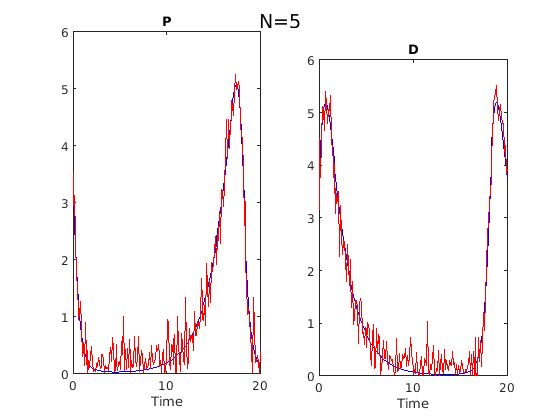

gsua_eval(T_est.Estlsqc(:,1:5),T_est,xdata,ydata);

**7. **Análisis de identificabilidad para las estiamciones realizadas

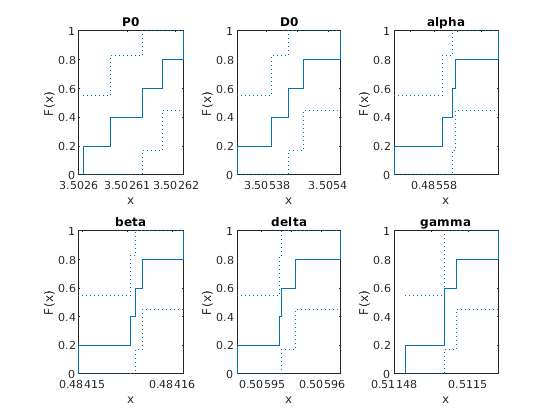

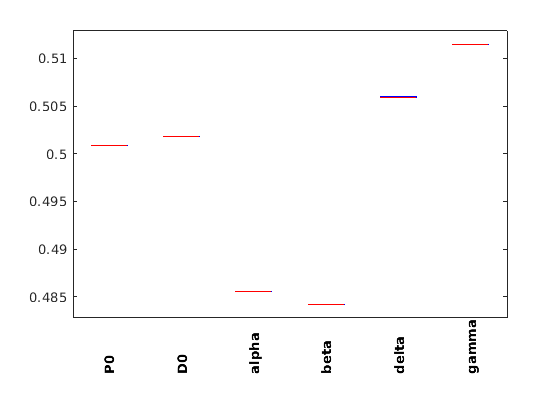

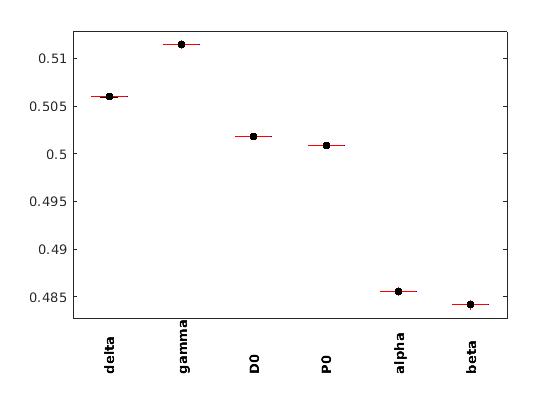

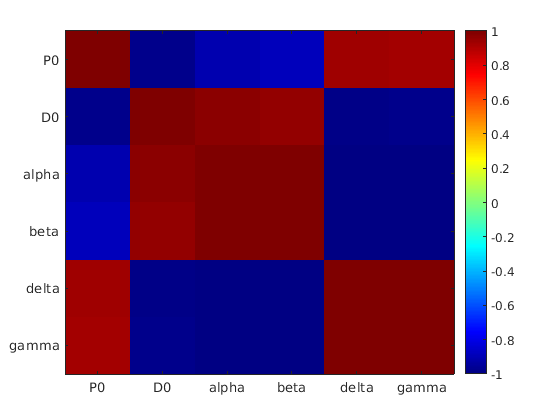

T = 6×5 table
                   Range           Nominal       Estlsqc                               Est                             index 
             __________________    _______    _____________    ___________________________________________________    _______

    P0        3.5026     3.5026     3.5026    [1×10 double]     3.5026     3.5026     3.5026     3.5026     3.5026    0.48483
    D0        3.5054     3.5054     3.5054    [1×10 double]     3.5054     3.5054     3.5054     3.5054     3.5054    0.49496
    alpha    0.48558    0.48559    0.48558    [1×10 double]    0.48558    0.48558    0.48559    0.48558    0.48557    0.49504
    beta     0.48415    0.48416    0.48416    [1×10 double]    0.48416    0.48416    0.48416    0.48416    0.48415   

T_ia = gsua_ia(T_est,T_est.Estlsqc(:,1:5), false, false);